BÁO CÁO THỰC HÀNH LAB 4

Cau 1 & 2:

clear;clc
data=[1 0 0 1];
addbit = [0 0 0];
bit_data = [data addbit];
div=[1 0 1 1];
[q,r]=deconv(bit_data,div);
r = mod(r,2);
tx_data = bitxor(bit_data,r);

Cau 3:

rx_data = bsc(tx_data,0.2);
% Check
[qcheck, rcheck] = deconv(rx_data,div);
rcheck = mod(rcheck,2);
check = sum(rcheck);
if check ~= 0
    disp("Retransmission Required");
else
    disp("TRANSMISSION SUCCESSFUL");
end

Retransmission Required


Cau 4&5:

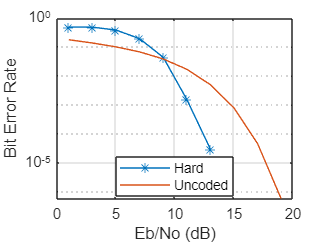

clear; clc
rng default
M = 64; % Modulation order
k = log2(M); % Bits per symbol
EbNoVec = (1:2:20); % Eb/No values (dB)
numSymPerFrame = 1000; % Number of QAM symbols per frame
berEstHard = zeros(size(EbNoVec));
trellis = poly2trellis(7,[171 133]);
tbl = 32;
rate = 1/2;
for n = 1:length(EbNoVec)
    % Convert Eb/No to SNR
    snrdB = EbNoVec(n) + 10*log10(k*rate);
    % Noise variance calculation for unity average signal power.
    noiseVar = 10.^(-snrdB/10);
    % Reset the error and bit counters
    [numErrsHard,numBits] = deal(0);
    while numErrsHard < 100 && numBits < 1e7
        % Generate binary data and convert to symbols
        dataIn = randi([0 1],numSymPerFrame*k,1);
        % Convolutionally encode the data
        dataEnc = convenc(dataIn,trellis);
        % QAM modulate
        txSig = qammod(dataEnc,M,'InputType','bit','UnitAveragePower',...
            true);
        % Pass through AWGN channel
        rxSig = awgn(txSig,snrdB,'measured');
        % Demodulate the noisy signal using harddecision (bit) and
        % soft decision (approximate LLR) approaches.
        rxDataHard = qamdemod(rxSig,M,'OutputType','bit','UnitAveragePower'...
            ,true);

        % Viterbi decode the demodulated data
        dataHard = vitdec(rxDataHard,trellis,tbl,'cont','hard');

        % Calculate the number of bit errors in the frame. Adjust for the
        % decoding delay, which is equal to the traceback depth.

        numErrsInFrameHard = biterr(dataIn(1:end- tbl),dataHard(tbl+1:end));

        % Increment the error and bit counters
        numErrsHard = numErrsHard + numErrsInFrameHard;
        numBits = numBits + numSymPerFrame*k;
    end
    % Estimate the BER for both methods
    berEstHard(n) = numErrsHard/numBits;
end
%Plot the estimated hard and soft BER data. Plot the theoretical performance for an uncoded 64-QAM channel.
semilogy(EbNoVec, [berEstHard],'-*')
hold on
semilogy(EbNoVec,berawgn(EbNoVec,'qam',M))
legend('Hard','Uncoded','location','best')
grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')

Cau 6:

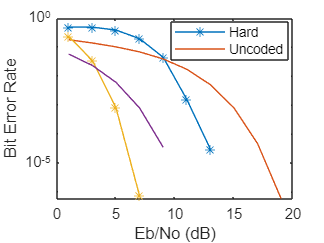

clear; clc
rng default
M = 4; % Modulation order
k = log2(M); % Bits per symbol
EbNoVec = (1:2:10); % Eb/No values (dB)
numSymPerFrame = 1000; % Number of QAM symbols per frame
berEstHard = zeros(size(EbNoVec));
trellis = poly2trellis(7,[171 133]);
tbl = 32;
rate = 1/2;
for n = 1:length(EbNoVec)
    % Convert Eb/No to SNR
    snrdB = EbNoVec(n) + 10*log10(k*rate);
    % Noise variance calculation for unity average signal power.
    noiseVar = 10.^(-snrdB/10);
    % Reset the error and bit counters
    [numErrsHard,numBits] = deal(0);
    while numErrsHard < 100 && numBits < 1e7
        % Generate binary data and convert to symbols
        dataIn = randi([0 1],numSymPerFrame*k,1);
        % Convolutionally encode the data
        dataEnc = convenc(dataIn,trellis);
        % QAM modulate
        txSig = qammod(dataEnc,M,'InputType','bit','UnitAveragePower',...
            true);
        % Pass through AWGN channel
        rxSig = awgn(txSig,snrdB,'measured');
        % Demodulate the noisy signal using harddecision (bit) and
        % soft decision (approximate LLR) approaches.
        rxDataHard = qamdemod(rxSig,M,'OutputType','bit','UnitAveragePower'...
            ,true);

        % Viterbi decode the demodulated data
        dataHard = vitdec(rxDataHard,trellis,tbl,'cont','hard');

        % Calculate the number of bit errors in the frame. Adjust for the
        % decoding delay, which is equal to the traceback depth.

        numErrsInFrameHard = biterr(dataIn(1:end- tbl),dataHard(tbl+1:end));

        % Increment the error and bit counters
        numErrsHard = numErrsHard + numErrsInFrameHard;
        numBits = numBits + numSymPerFrame*k;
    end
    % Estimate the BER for both methods
    berEstHard(n) = numErrsHard/numBits;
end
%Plot the estimated hard and soft BER data. Plot the theoretical performance for an uncoded 64-QAM channel.
semilogy(EbNoVec, [berEstHard],'-*')
hold on
semilogy(EbNoVec,berawgn(EbNoVec,'qam',M))
legend('Hard','Uncoded','location','best')
grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')